# Clustering and the Poisson Distribution

We have seen in Chapter 5 that the Poisson distribution can be used to describe spatially random processes. Let's examine this numerically by creating a simulation. We will create a set of randomly distributed points on a square between the values of 0 and 1. Then, we will use Matlab to divide the square into smaller squares and calculate the number of points lying in each square. We can then calculate the histogram of the number of points within each cell and calculate the mean and variance as well to see if they are the same. 

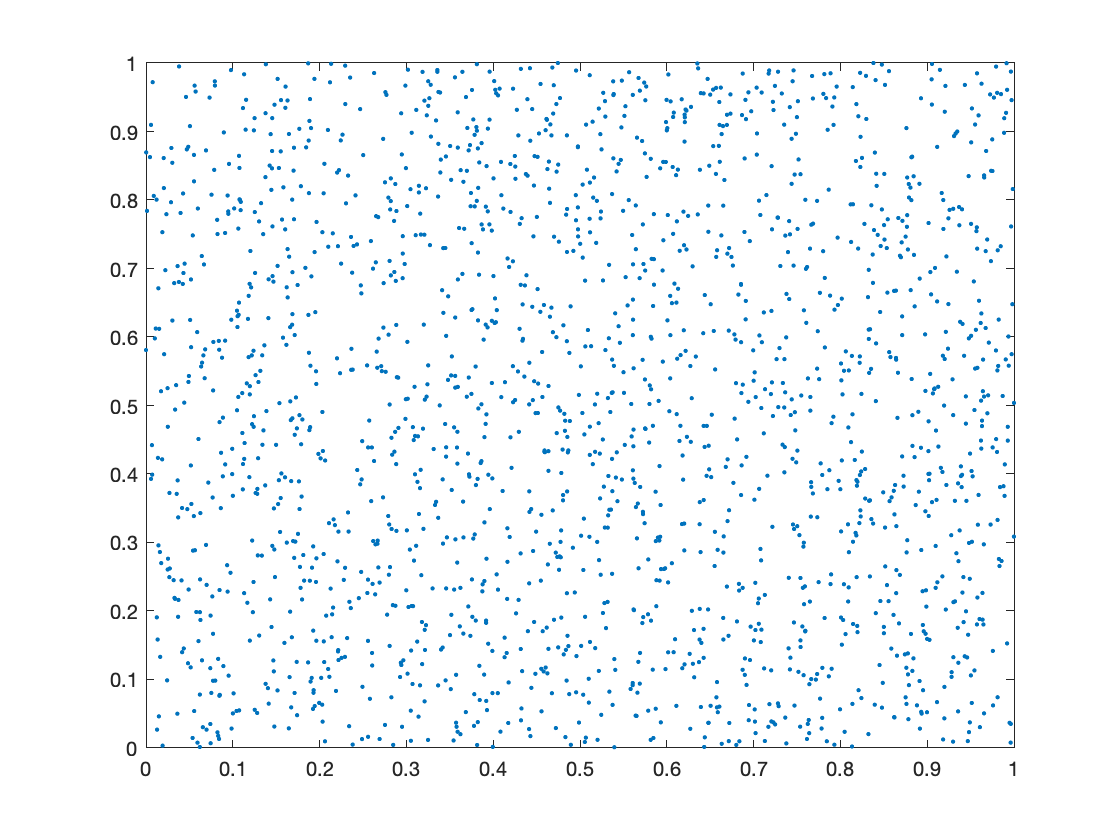

% Specify the number of points we want in our plot 
n_points = 2000;

% Generate randomly distributed x and y coordinates for these points using
% a uniform distribution between 0 and 1
x = rand(n_points,1);
y = rand(n_points,1);

% Plot out the field of points
figure(1)
plot(x,y,'.')

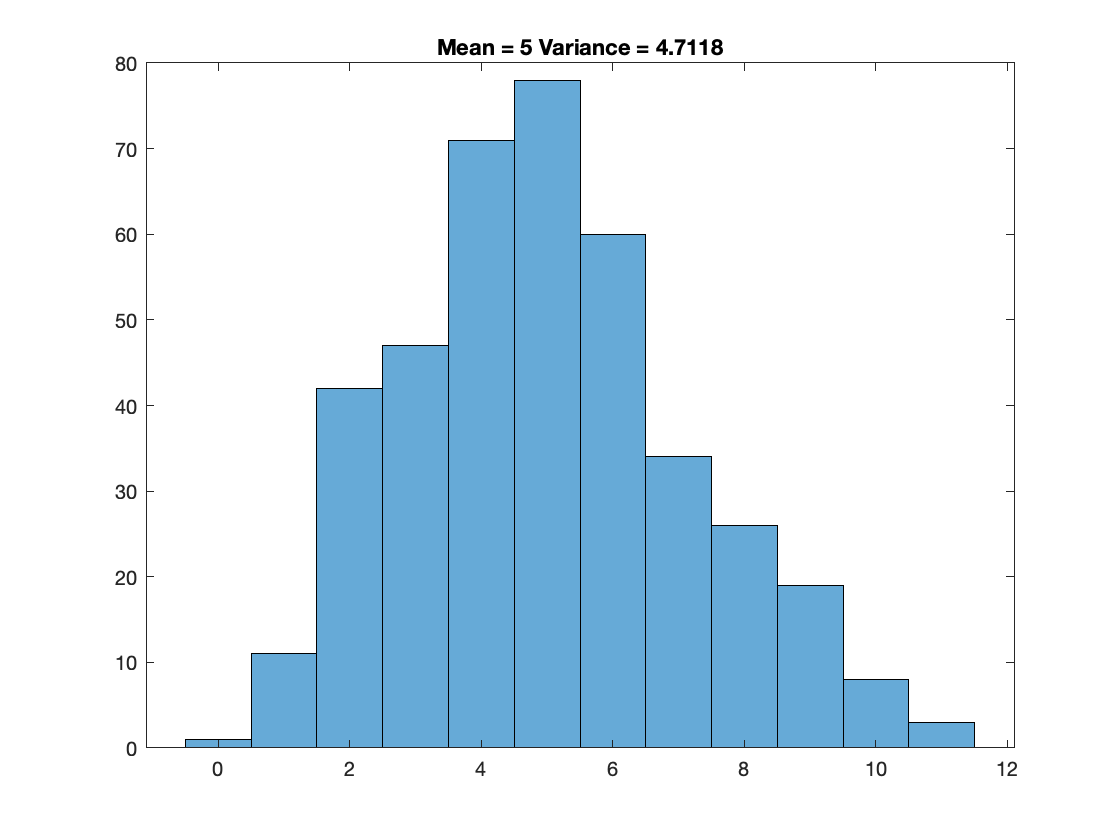


% Specify the number of bins we want to divide the square into
n_bins = 20;

% Calculate the number of points within in bin and plot the histogram
[N, x_edges, y_edges] = histcounts2(x,y, n_bins);
figure(2)
histogram(N)
title(['Mean = ' num2str(mean(reshape(N,n_bins*n_bins,1))) ' Variance = ' num2str(var(reshape(N,n_bins*n_bins,1)))])

The resulting distribution is definitely skewed with a tail at higher numbers, and the mean and variance are approximately the same. 

***Exercise:**** Investigate how things change as you change the number of points and the number of bins. Does this agree with your intuition about the Poisson distribution?*

Now let's change the simulation so that if a point lies sufficiently close to another, we eliminate it. 

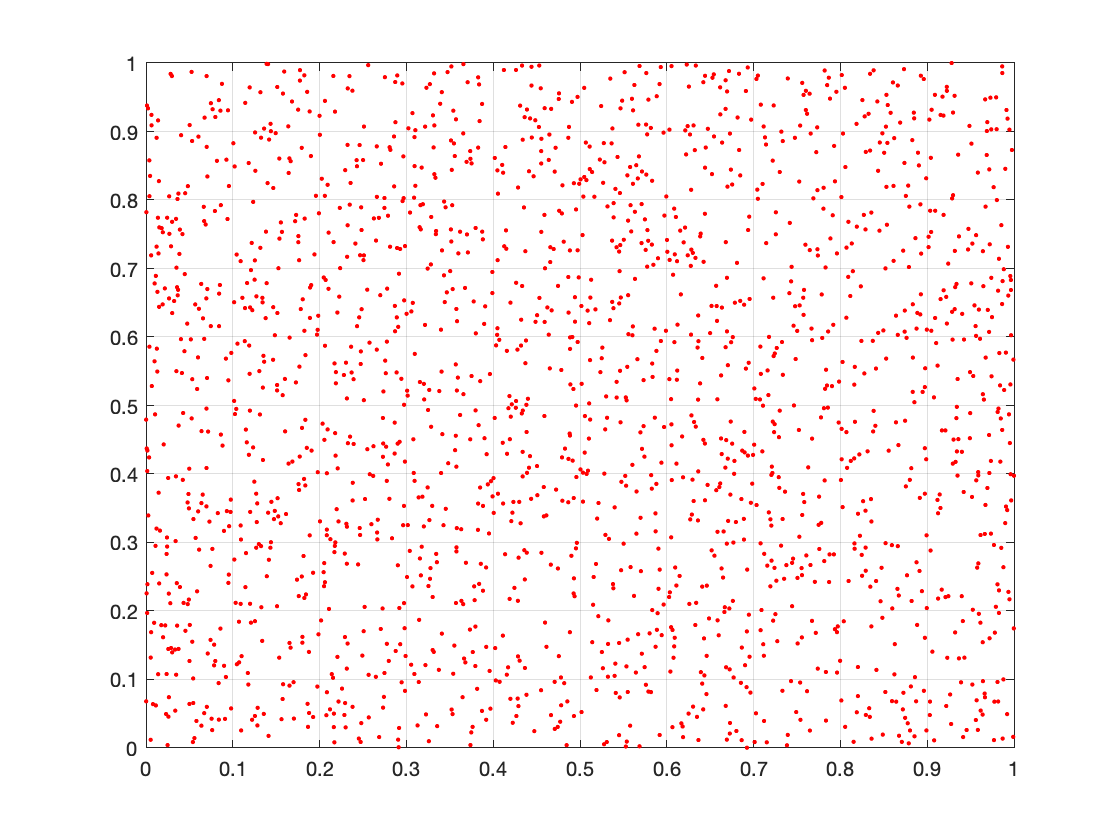

% Specify the number of points we want in our plot 
%n_points = 1000;

% Generate randomly distributed x and y coordinates for these points using
% a uniform distribution between 0 and 1
%x = rand(n_points,1);
%y = rand(n_points,1);

%radius = 0.1;

%[i_bin, j_bin, bin_x, bin_y] = ClusterPointsMMEES(x, y, radius);

%figure(3)
%plot(x,y, 'b.',x(i_bin), y(j_bin), 'r.')
%grid on

a = 0.0;
b = 1.0;

[x_point, y_point, n_point] = ClusterPoints2(a, b);

figure(4)
plot(x_point, y_point, 'r.')
grid on

Looks similar, but is it? 

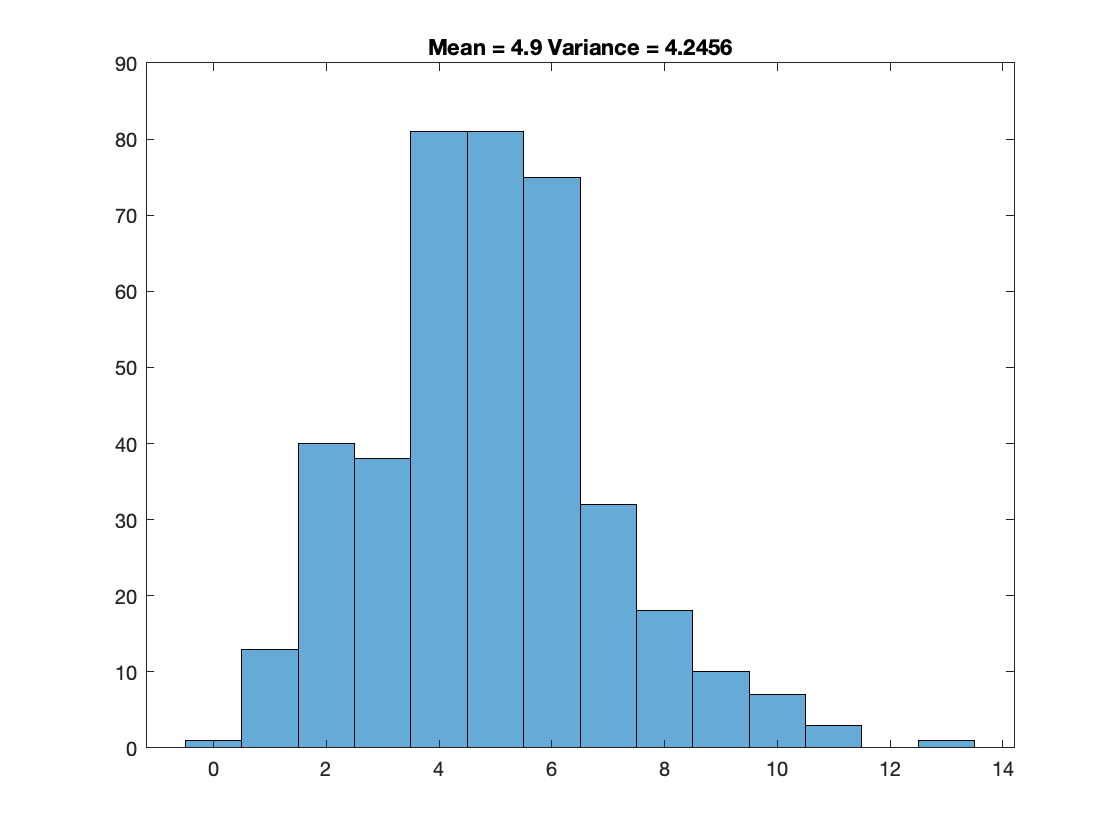

% Specify the number of bins we want to divide the square into
n_bins = 20;

% Calculate the number of points within in bin and plot the histogram
[N, x_edges, y_edges] = histcounts2(x_point, y_point, n_bins);
figure(2)
histogram(N)
title(['Mean = ' num2str(mean(reshape(N,n_bins*n_bins,1))) ' Variance = ' num2str(var(reshape(N,n_bins*n_bins,1)))])

We see that the variance is less than the mean and so the distribution of points is less clumped than random. This makes sense because we've designed the second simulation such that points do not have direct neighbors. Notice that these are random simulations and so sometimes you might see a variance that is closer to the value of the mean than in others. 